# Homework 3: Chaotic time series prediction

The files [training_set.csv](https://nn-2022.opentaproject.com/exercise/97f1e8f0-aefb-4039-b2f2-c5bfe53cacd7/asset/training-set.csv) and [test_set.csv](https://nn-2022.opentaproject.com/exercise/97f1e8f0-aefb-4039-b2f2-c5bfe53cacd7/asset/test-set-6.csv) contain 3-dimensional time series generated from the chaotic Lorenz dynamics (see [link](https://en.wikipedia.org/wiki/Lorenz_system)). The time series was generated using a time step size of $dt=0.02$ seconds. Use the training set to train a reservoir computer to predict the Lorenz dynamics.

The reservoir has $N = 3$ input neurons and 500 reservoir neurons. The input weights $w_{ij}^{(in)}$and reservoir weights $w_{ij}

$ are independent Gaussian random numbers with mean zero and variances 0.002 and 2/500 respectively.

Use the following update rule for the reservoir dynamics


$$r_i(t+1)=\tanh \left(\sum_j w_{i j} r_j(t)+\sum_{k=1}^N w_{i k}^{(i n)} x_k(t)\right)$$


The output of the reservoir computer is given by


$$O_i(t) = \sum_{j=1}w_{ij}^{(out)}r_j(t)
$$


Train the output weights $w_{ij}^{(out)}
$ using ridge regression with ridge parameter $k=0.01 $(see [link](https://en.wikipedia.org/wiki/Ridge_regression)). When the test data has been fed through the network, use the following update rules to predict the continuation of the test data:


$$r_i(t+1) = \tanh \Big ( \sum_{j=1}^N w_{ij}r_j(t) + \sum_{k=1}^nw_{ik}^{(in)}O_k(t) \Big )$$


Use the reservoir to predict 500 time steps and save the *y*-component of the output $O_2(t) 
$ for every time step. After training, feed the test data through the network using the same update rules. Note that the output should be saved starting from $O_2(T+1)$, where $T$ is the length of the test set. Thus, the saved data will range from $O_2(T+1)$ to $O_2(T+501)$.

clc
clear
w_in = normrnd(0,0.002,[500,3]); % 500x3
w_reservoir = normrnd(0,2/500, [500,500]); % 500x500
w_reservoir = w_reservoir -  diag(w_reservoir);
w_out = zeros([3,500]); % 3x500
input = csvread("training-set.csv");
test_data = csvread("test-set-6.csv");
input_length = size(input,2);
test_length = size(test_data, 2);
k = 0.01;

## Plotting

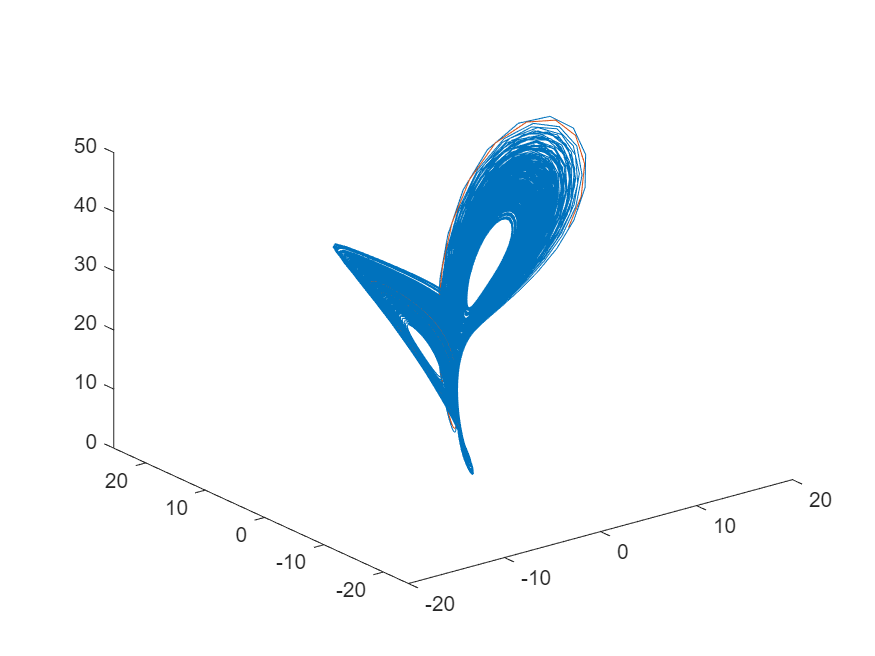

figure
plot3(input(1,:), input(2,:),input(3,:))
hold on 
plot3(test_data(1,:), test_data(2,:),test_data(3,:))

R = zeros([500,1]); % 500x1
R_old = R;
for epoch=1:5
    for idx=1:input_length
        R(:,idx) = tanh(w_reservoir*R_old + w_in * input(:,idx));
        R_old = R(:,idx);
    end
    w_out = input*R'*inv((R*R'+k*eye(500)));
end

R_old = zeros([500,1]);
R = R_old;
for idx=1:test_length
    R(:,idx) = tanh(w_reservoir*R_old + w_in * test_data(:,idx));
    R_old = R(:,idx);
end
O = w_out *R;
R_old = zeros([500,1]);
neuron_R = R_old;
for step=1:500
    neuron_R = tanh(w_reservoir*R_old + w_in * O(:,test_length+step-1));
    O(:,test_length+step) = w_out*neuron_R;
    R_old = neuron_R;
end

y = O(2,101:end)';
csvwrite("prediction.csv",y);

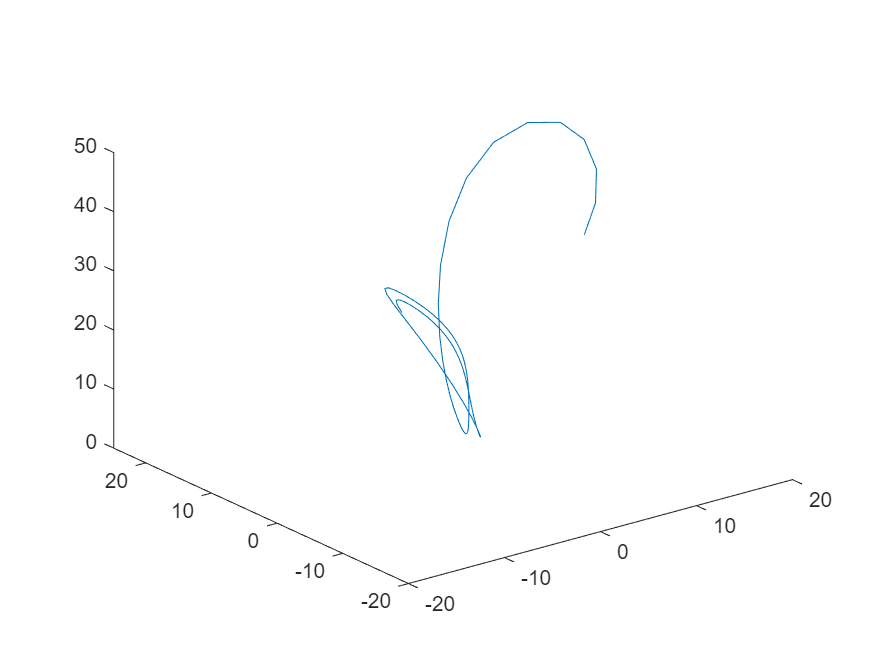

figure
plot3(test_data(1,:), test_data(2,:),test_data(3,:))

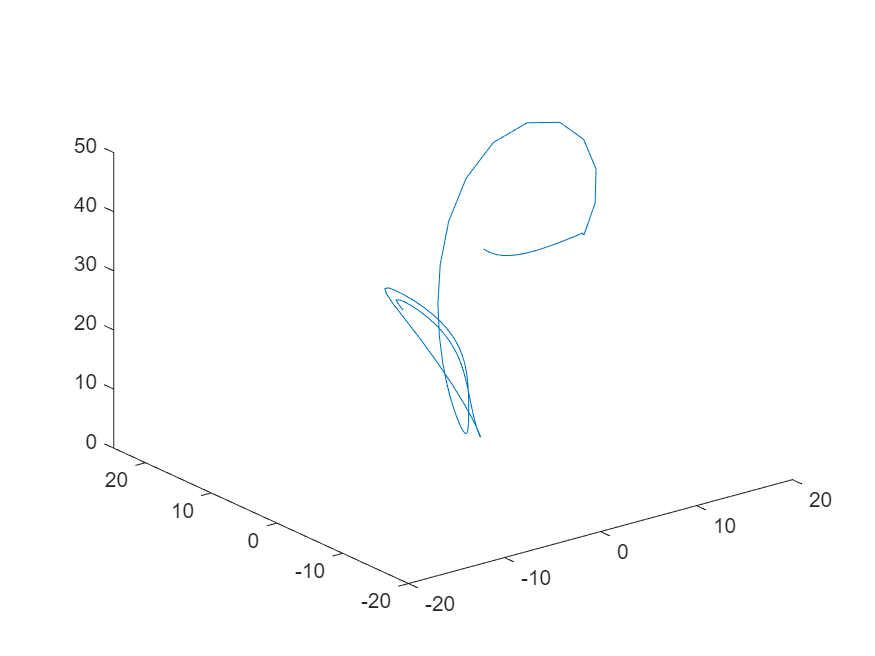

% hold on
plot3(O(1,:), O(2,:),O(3,:))